% AAE 532 HW 10 Problem 4 Extra
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps10';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
mars = planet_consts.mars;  % structure of mars
earth = planet_consts.earth;  % structure of earth
sun = planet_consts.sun;  % structure of sun
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

mu_sun = sun.gp;  % gravitational parameter of sun
mu_earth = earth.gp;  % gravitational parameter of earth 
mu_mars = mars.gp;  % gravitational parameter of mars 
R_mars = mars.mer;  % radius of Mars
R_earth = earth.mer;  % radius of earth

r1 = earth.smao  % the first leg of the space triangle equal to the semi-major axis of earth

r1 = 149597898

r2 = mars.smao  % the second leg of the space triangle equal to the semi-major axis of mars

r2 = 227944135

v1 = sqrt(mu_sun / r1);  % initial velocity in the orbit of earth
v2 = sqrt(mu_sun / r2);  % final velocity in the orbit of mars

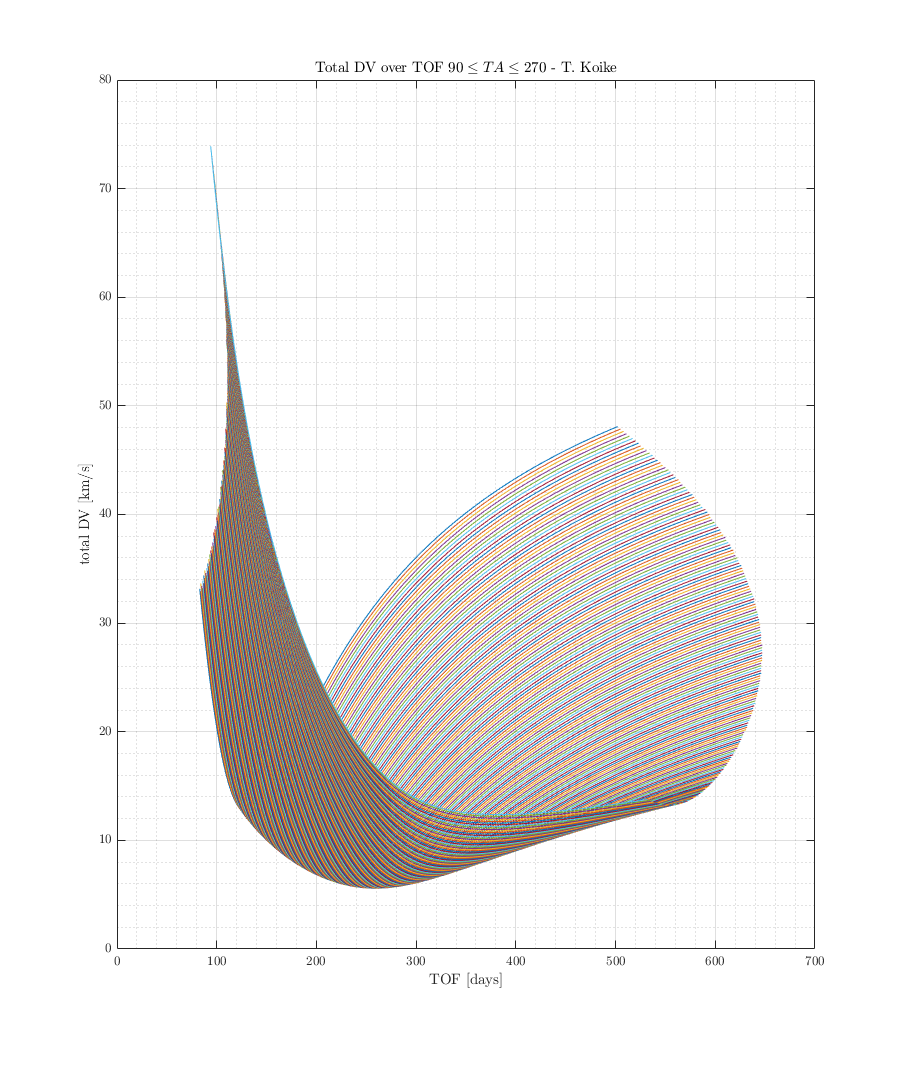

Dv_min_all = [];
TOF_min_all = [];
TrA_array = 90:270;
% Plot
fig1 = figure("Renderer","painters","Position",[10 10 900 1200]);
for TrA = TrA_array
    
    if TrA < 180
        c = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(TrA));  % chord length of the space triangle
        typehold = "1";
    else
        c = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(360 - TrA));
        typehold = "2";
    end
    
    s = (r1 + r2 + c) / 2;  % semi-perimeter
    % TOF for parabolic orbit
    TOF_para = lambertTOF_para(mu_sun, s, c, typehold);
    TOF_para_days = TOF_para / 60 / 60 / 24;
    
    % Check which type of elliptical transfer
    a_min = s/2;  % the minimum possible semi-major axis of the transfer orbit
    alpha_o = 2*asin(sqrt(s / 2 / a_min));  % base alpha parameter
    beta_o = 2*asin(sqrt((s - c) / 2 / a_min));  % base beta parameter
    % Calculate the minimum TOF using lambert equation
    temp = typehold + "A";
    TOF_min = lambert_ellip(alpha_o, beta_o, mu_sun, "TOF", temp, a_min);
    TOF_min_days = TOF_min / 60 / 60 / 24;

    % Preallocate total DV vector 
    Dv_tot_array = [];
    
    % For loop to find the optimal TOF for given space triangle 
    TOF_days_array = round(TOF_para_days)+1:TOF_min_days*2.5;
    for TOF_days = TOF_days_array
        revert = 0;
        TOF = TOF_days * 60 * 60 * 24;  % TOF [s]
        if TOF > TOF_min
            type = typehold + "B";
        else
            type = typehold + "A";
        end
        % Find the SMA corresponding to the TOF
        [a, alpha, beta, fval] = find_lambertEllip_SMA(s, c, TOF, mu_sun, a_min, type);
        
        [p, e, TA_dep, TA_arr, p_db, TA_dep_db, TA_arr_db] = find_lambertX_ellip(a, alpha, ...
            beta, TrA, s, c, r1, r2, mu_sun, TOF_days, "day");
        
        % Calculate energy
        En = -mu_sun / 2 / a;
        % Velocity and FPA
        v_dep = vis_viva(r1, a, mu_sun);
        v_arr = vis_viva(r2, a, mu_sun);
        FPA_dep = acos_dbval(sqrt(mu_sun * p)/r1 / v_dep, "deg");
        FPA_arr = acos_dbval(sqrt(mu_sun * p)/r2 / v_arr, "deg");
        if TA_dep > 0
            FPA_dep = FPA_dep(FPA_dep > 0);
        else
            FPA_dep = FPA_dep(FPA_dep < 0);
        end
        if TA_arr > 0
            FPA_arr = FPA_arr(FPA_arr > 0);
        else
            FPA_arr = FPA_arr(FPA_arr < 0);
        end
        
        % Departure 
        Dv_dep = sqrt(v_dep^2 + v1^2 - 2 * v_dep * v1 * cosd(FPA_dep));
        % Arrival 
        Dv_arr = sqrt(v_arr^2 + v2^2 - 2 * v_arr * v2 * cosd(FPA_arr));
        % Total
        Dv_tot = Dv_dep + Dv_arr;
        if isempty(Dv_tot)
            Dv_tot_array = [Dv_tot_array, NaN];
        else
            Dv_tot_array = [Dv_tot_array, Dv_tot];
        end
    end
    [TF, P] = islocalmin(Dv_tot_array);
    Dv_mins = Dv_tot_array(TF);
    TOF_mins = TOF_days_array(TF);
    dvmin = Dv_mins(1);
    tofmin = TOF_mins(1);
    TOF_min_all = [TOF_min_all, tofmin];
    Dv_min_all = [Dv_min_all, dvmin];
    
    
    hold on; grid on; grid minor; box on;
    plot(TOF_days_array, Dv_tot_array, '-')
end
hold off;
title('Total DV over TOF $90\leq TA\leq 270$ - T. Koike')
xlabel('TOF [days]')
ylabel('total DV [km/s]')
saveas(fig1, fullfile(fdir, "p4_DV_TOF_TArange.png"));

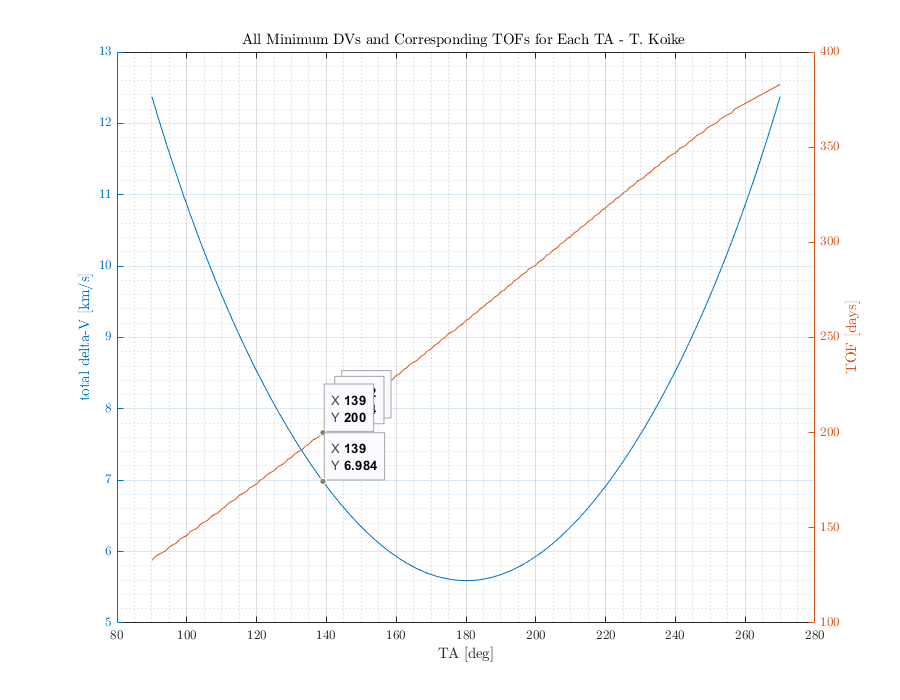

% Another plot
fig2 = figure("Renderer","painters","Position",[10 10 900 700]);
yyaxis left
plot(TrA_array, Dv_min_all)
ylabel('total delta-V [km/s]')
yyaxis right
plot(TrA_array, TOF_min_all)
ylabel('TOF [days]')
title('All Minimum DVs and Corresponding TOFs for Each TA - T. Koike ')
xlabel('TA [deg]')
grid on; grid minor; box on;
saveas(fig2, fullfile(fdir, 'p4_minDV_TOF.png'));

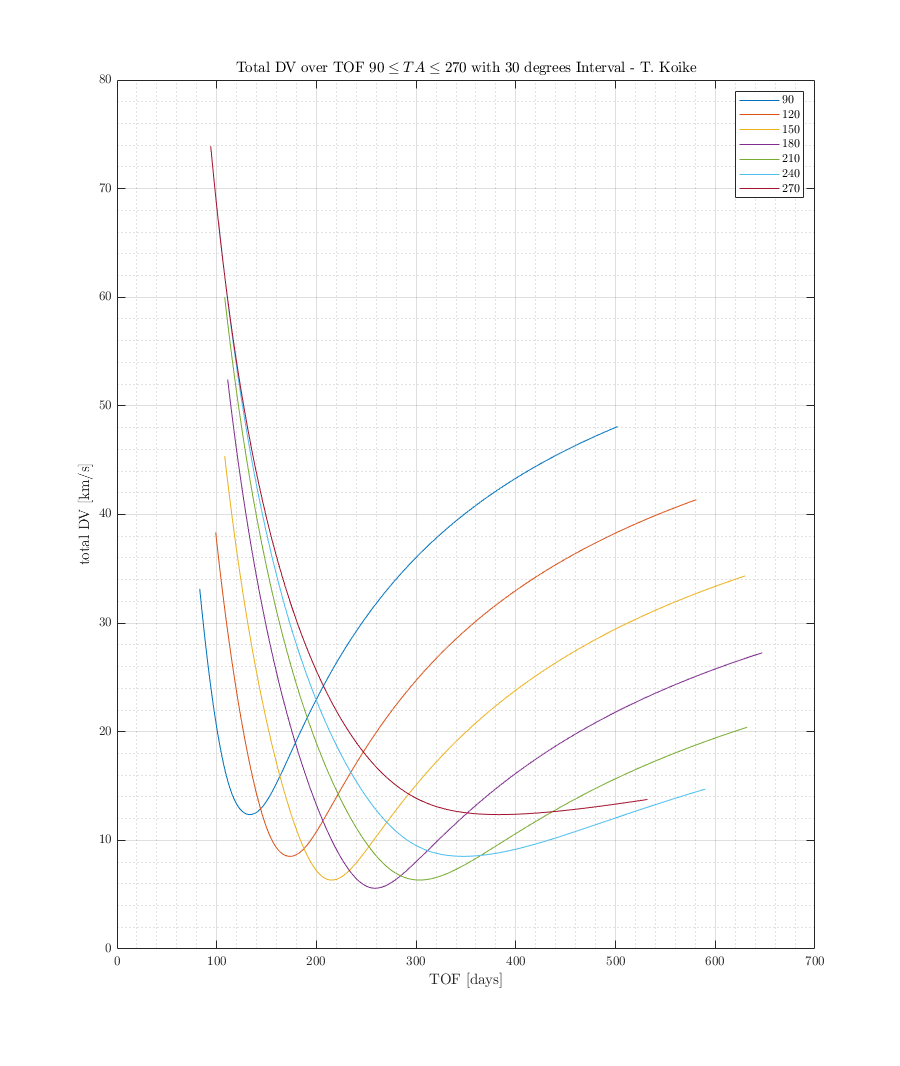

Dv_min_all = [];
TOF_min_all = [];
TrA_array = 90:30:270;
% Plot
fig3 = figure("Renderer","painters","Position",[10 10 900 1200]);
for TrA = TrA_array
    
    if TrA < 180
        c = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(TrA));  % chord length of the space triangle
        typehold = "1";
    else
        c = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(360 - TrA));
        typehold = "2";
    end
    
    s = (r1 + r2 + c) / 2;  % semi-perimeter
    % TOF for parabolic orbit
    TOF_para = lambertTOF_para(mu_sun, s, c, typehold);
    TOF_para_days = TOF_para / 60 / 60 / 24;
    
    % Check which type of elliptical transfer
    a_min = s/2;  % the minimum possible semi-major axis of the transfer orbit
    alpha_o = 2*asin(sqrt(s / 2 / a_min));  % base alpha parameter
    beta_o = 2*asin(sqrt((s - c) / 2 / a_min));  % base beta parameter
    % Calculate the minimum TOF using lambert equation
    temp = typehold + "A";
    TOF_min = lambert_ellip(alpha_o, beta_o, mu_sun, "TOF", temp, a_min);
    TOF_min_days = TOF_min / 60 / 60 / 24;

    % Preallocate total DV vector 
    Dv_tot_array = [];
    
    % For loop to find the optimal TOF for given space triangle 
    TOF_days_array = round(TOF_para_days)+1:TOF_min_days*2.5;
    for TOF_days = TOF_days_array
        revert = 0;
        TOF = TOF_days * 60 * 60 * 24;  % TOF [s]
        if TOF > TOF_min
            type = typehold + "B";
        else
            type = typehold + "A";
        end
        % Find the SMA corresponding to the TOF
        [a, alpha, beta, fval] = find_lambertEllip_SMA(s, c, TOF, mu_sun, a_min, type);
        
        [p, e, TA_dep, TA_arr, p_db, TA_dep_db, TA_arr_db] = find_lambertX_ellip(a, alpha, ...
            beta, TrA, s, c, r1, r2, mu_sun, TOF_days, "day");
        
        % Calculate energy
        En = -mu_sun / 2 / a;
        % Velocity and FPA
        v_dep = vis_viva(r1, a, mu_sun);
        v_arr = vis_viva(r2, a, mu_sun);
        FPA_dep = acos_dbval(sqrt(mu_sun * p)/r1 / v_dep, "deg");
        FPA_arr = acos_dbval(sqrt(mu_sun * p)/r2 / v_arr, "deg");
        if TA_dep > 0
            FPA_dep = FPA_dep(FPA_dep > 0);
        else
            FPA_dep = FPA_dep(FPA_dep < 0);
        end
        if TA_arr > 0
            FPA_arr = FPA_arr(FPA_arr > 0);
        else
            FPA_arr = FPA_arr(FPA_arr < 0);
        end
        
        % Departure 
        Dv_dep = sqrt(v_dep^2 + v1^2 - 2 * v_dep * v1 * cosd(FPA_dep));
        % Arrival 
        Dv_arr = sqrt(v_arr^2 + v2^2 - 2 * v_arr * v2 * cosd(FPA_arr));
        % Total
        Dv_tot = Dv_dep + Dv_arr;
        if isempty(Dv_tot)
            Dv_tot_array = [Dv_tot_array, NaN];
        else
            Dv_tot_array = [Dv_tot_array, Dv_tot];
        end
    end
    [TF, P] = islocalmin(Dv_tot_array);
    Dv_mins = Dv_tot_array(TF);
    TOF_mins = TOF_days_array(TF);
    dvmin = Dv_mins(1);
    tofmin = TOF_mins(1);
    TOF_min_all = [TOF_min_all, tofmin];
    Dv_min_all = [Dv_min_all, dvmin];
    
    
    hold on; grid on; grid minor; box on;
    plot(TOF_days_array, Dv_tot_array, '-')
end
hold off;
title('Total DV over TOF $90\leq TA\leq 270$ with 30 degrees Interval - T. Koike')
xlabel('TOF [days]')
ylabel('total DV [km/s]')
legend('90','120','150','180','210','240','270')
saveas(fig3, fullfile(fdir, "p4_DV_TOF_TArange_30.png"));